#### Load data

data = readtable('Pressure_measurements.xlsx');

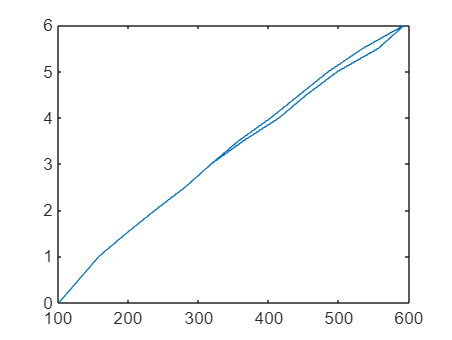


x = data.Pressure_analog_;
y = data.Pressure_bar_;

plot(x,y)

#### Fit linear model

p = polyfit(x, y, 1);   % 1 means linear fit

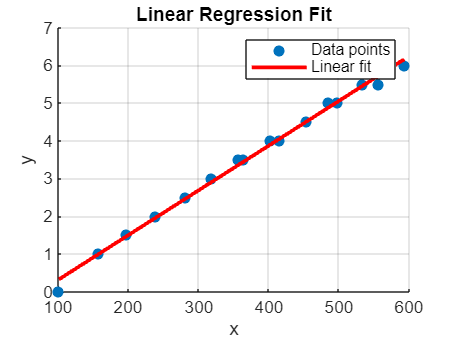

scatter(x, y, 'filled');   % plot the data points
hold on
yfit = polyval(p, x);       % compute the fitted y values
plot(x, yfit, '-r', 'LineWidth', 2);  % plot the fitted line
xlabel('x');
ylabel('y');
title('Linear Regression Fit');
legend('Data points', 'Linear fit');
grid on
hold off

#### Evaluation

yresid = y - yfit;                         % Residuals
SSresid = sum(yresid.^2);                  % Sum of squares of residuals
SStotal = sum((y - mean(y)).^2);            % Total sum of squares
Rsq = 1 - SSresid/SStotal                 % R^2

Rsq = 0.9945